# General Code Documentation

%
% @file     AM_Transmitter.mlx
%
% @brief    AM Transmitter and Receiver module.
%           Transmits a given signal.
%
% @author   Juan Orlando Cives Espejo
%
% @date     1/11/2024
%
% @version  2.0

clear all
close all
clc

## AM Modulation

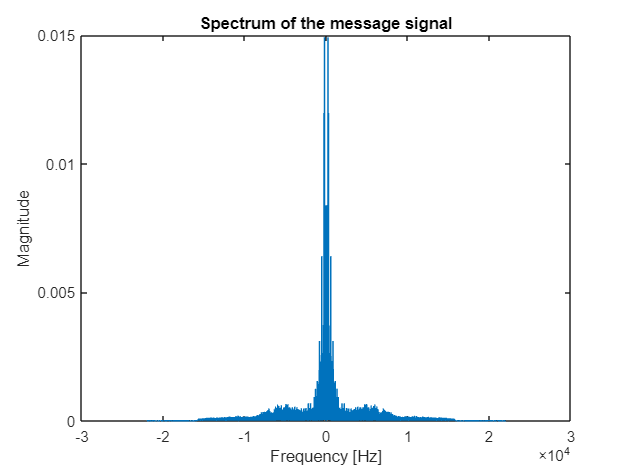

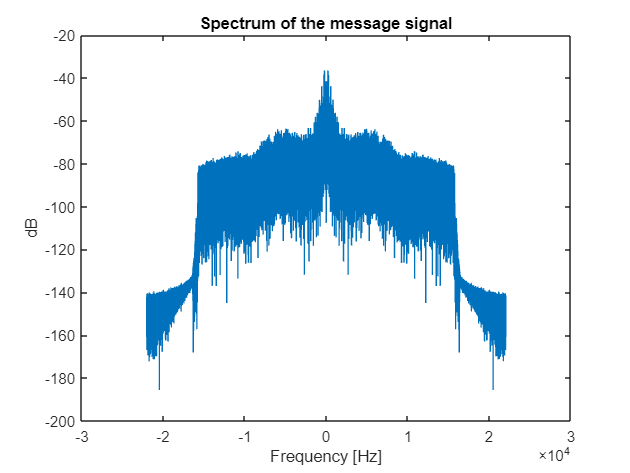

% Message signal generation
startSample = 500000;                                                                      
samples     = 500000;                                                    
path        = "C:\Users\Juan Orlando\OneDrive - Universidad Pontificia Comillas\Escritorio\TFG\" + ...
              "Matlab Simulink ficheros\Modulación AM\Transmison AM Rosas\rosas.mp3";
[messageSignal, fs, t] = createMessageSignal(path, startSample, samples, true);

% Carrier configuration [5 kHz]
f_c = 5e3;
carrier = exp(2 * pi * f_c * 1i * t);
carrier = carrier / max(carrier);

% Modulated signal configuration [modulation index = 1]
modulationIndex = 1;
amModulatedSignal = (1 + modulationIndex * messageSignal) .* carrier;
amModulatedSignal = amModulatedSignal / max(amModulatedSignal);

% Plots of the signals
showSpectrum(messageSignal, fs, "Spectrum of the message signal", true)

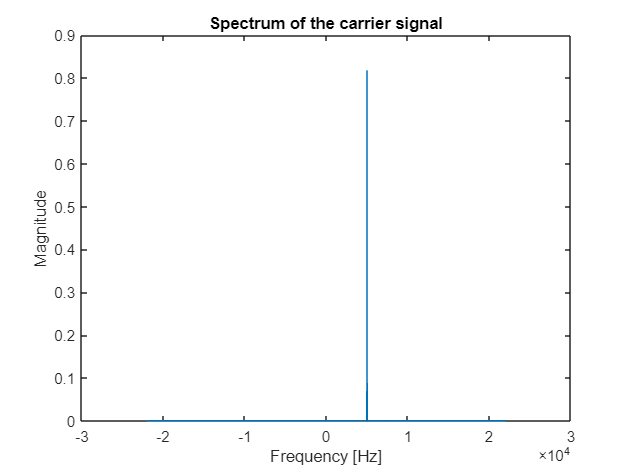

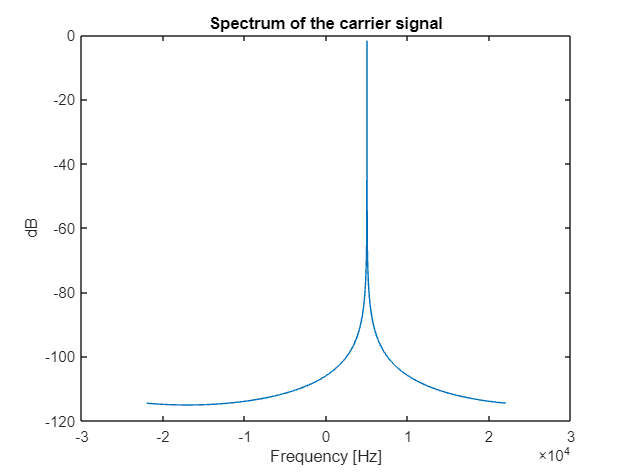

showSpectrum(carrier, fs, "Spectrum of the carrier signal", true)

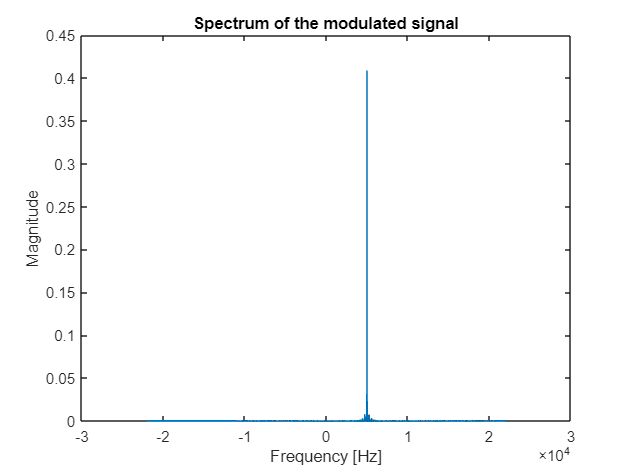

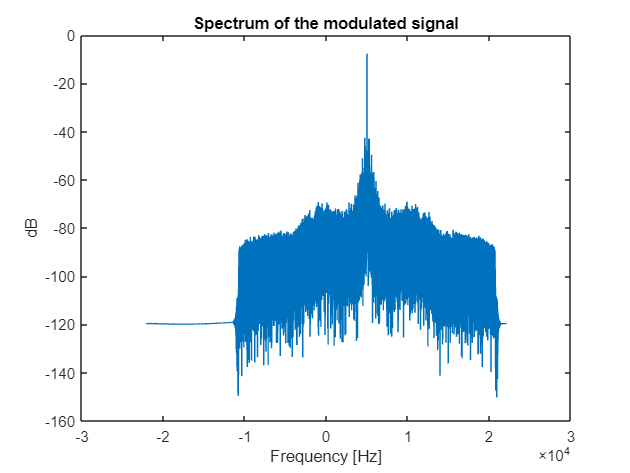

showSpectrum(amModulatedSignal, fs, "Spectrum of the modulated signal", true)

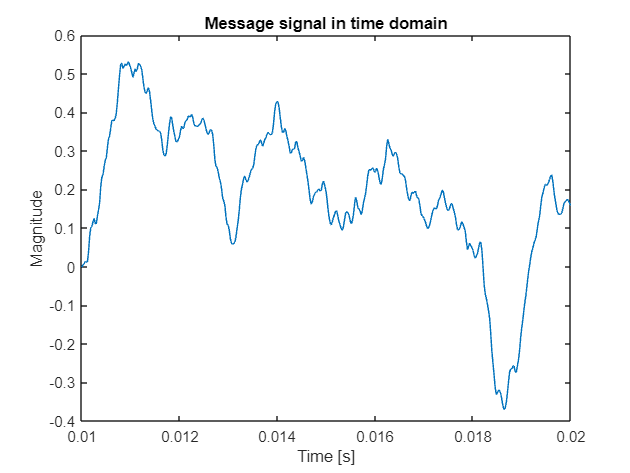

showTimeSignal(messageSignal, t, "Message signal in time domain")
xlim([0.01, 0.02])

showTimeSignal(amModulatedSignal, t, "Message signal in time domain")

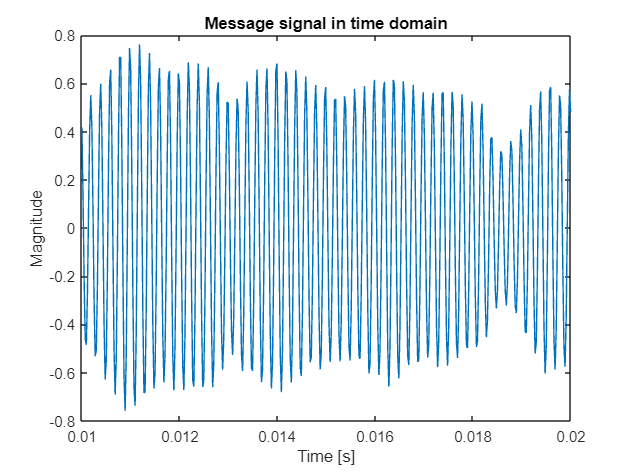

xlim([0.01, 0.02])

## Transmission of the signal

% Configuration of the transmitter and receiver
txGain          = -10;
rxGain          = 10;
frequecnyRF     = 2.2e9; 
fsAdalmPluto    = 500e3;

[tx, rx] = configurationPlutoTxRx(txGain, rxGain, frequecnyRF, fsAdalmPluto, samples);

dataRx   = transmitReceiveSignal(rx, tx, amModulatedSignal);

## Establishing connection to hardware. This process can take several seconds.
## Waveform transmission has started successfully and will repeat indefinitely. 
## Call the release method to stop the transmission.
## Establishing connection to hardware. This process can take several seconds.


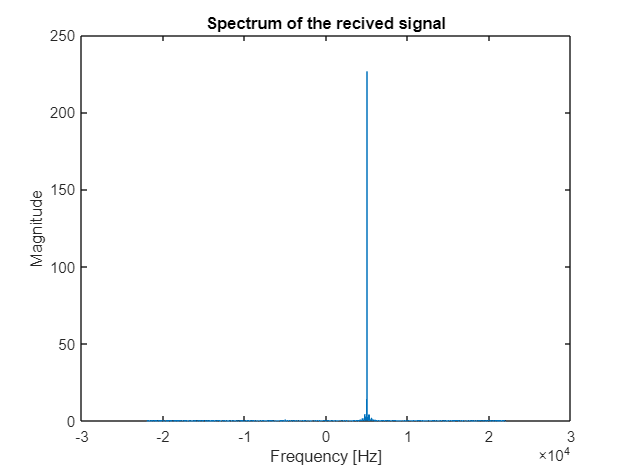

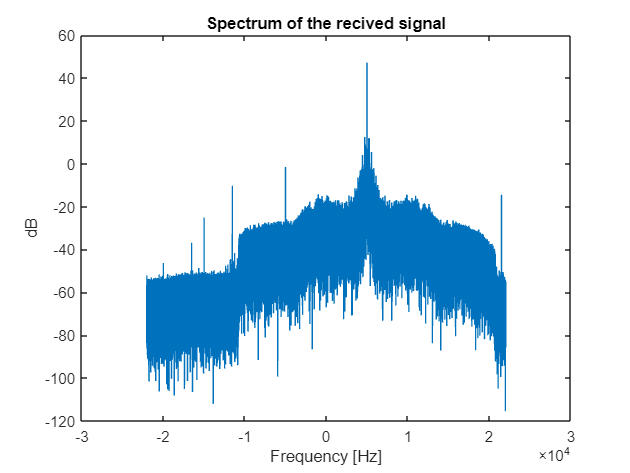


% Plot received data
showSpectrum(dataRx, fs, "Spectrum of the recived signal", true)

## AM Demodulation

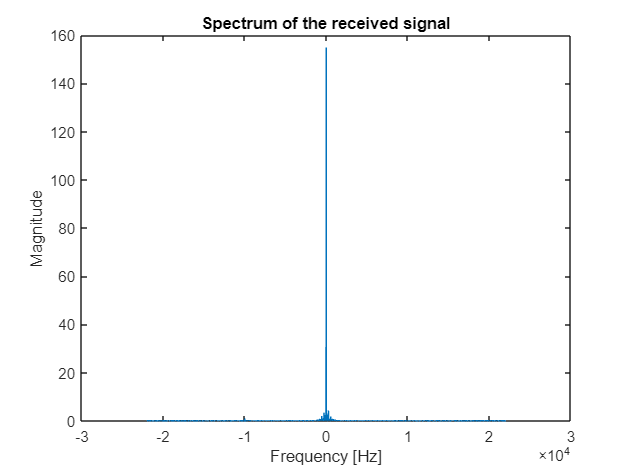

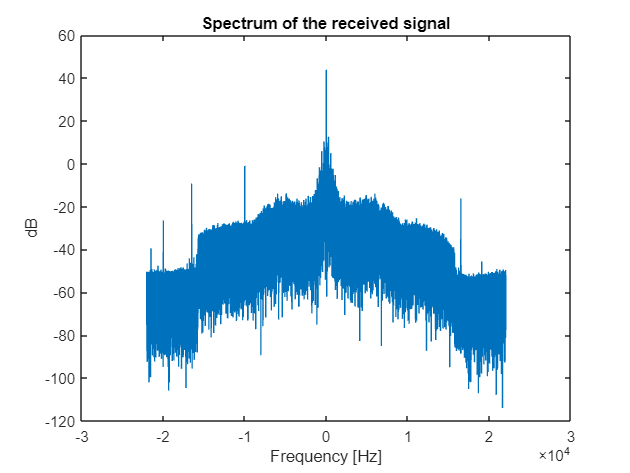

% Configuration of the demodulation carrier
demodulationCarrier =  exp(2 * pi * -f_c * 1i * t);
demodulationCarrier = demodulationCarrier / max(demodulationCarrier);

% Signal demodulation
rxSignal = dataRx.' .* demodulationCarrier;
signalEnvelope = abs(rxSignal);

% Eliminate DC component
demodulatedSignal = signalEnvelope - mean(signalEnvelope); 
showSpectrum(rxSignal, fs, "Spectrum of the received signal", true)

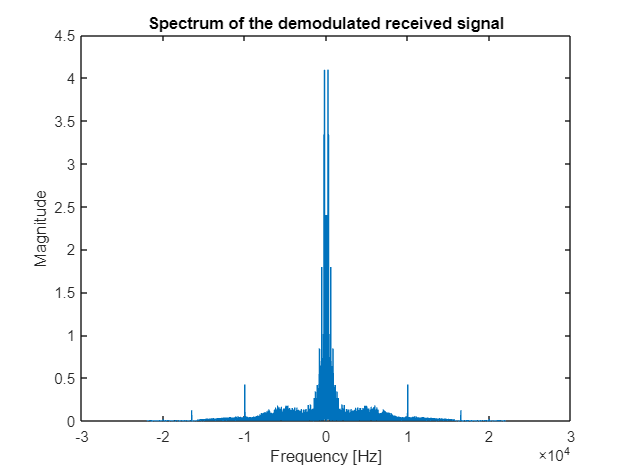

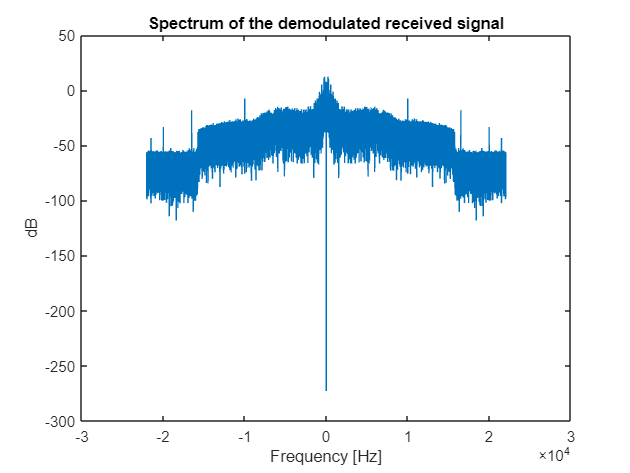

showSpectrum(demodulatedSignal, fs, "Spectrum of the demodulated received signal", true)